clc;clear,close all;

N=input("Enter the number of Joints:")

N = 3


theta=zeros(N,1);
di=zeros(N,1);
ai=zeros(N,1);
alpha=zeros(N,1);

T=zeros(4,4,N);
q=zeros(1,N);
T_Total=eye(4);

%This is for D-H Parameters and Transformation
for i=1:N
    theta(i)=deg2rad(input(sprintf("Enter the theata %d value:",i)));
    di(i)=input(sprintf("Enter the di %d value:",i));
    ai(i)=input(sprintf("Enter ai %d value:",i));
    alpha(i)=deg2rad(input(sprintf("Enter alpha %d value:",i)));
    
    T(:,:,i)=[cos(theta(i))  -sin(theta(i))*cos(alpha(i))  sin(theta(i))*sin(alpha(i))  ai(i)*cos(theta(i));
        sin(theta(i))   cos(theta(i))*cos(alpha(i))    -cos(theta(i))*sin(alpha(i))  ai(i)*sin(theta(i));
        0                sin(alpha(i))                 cos(alpha(i))                  di(i);
        0                 0                               0                             1];

    fprintf("Transformation matrix for Joint %d:",i);
    disp(T(:,:,i));

    L(i)=Link([theta(i) di(i) ai(i) alpha(i)]);

end

Transformation matrix for Joint 1:

   -0.5000   -0.0000    0.8660         0
    0.8660   -0.0000    0.5000         0
         0    1.0000    0.0000   30.0000
         0         0         0    1.0000



Transformation matrix for Joint 2:

   -0.5000   -0.8660         0  -15.0000
    0.8660   -0.5000         0   25.9808
         0         0    1.0000         0
         0         0         0    1.0000



Transformation matrix for Joint 3:

   -0.5000   -0.8660         0   -5.0000
    0.8660   -0.5000         0    8.6603
         0         0    1.0000         0
         0         0         0    1.0000




%This is for Jacobian
q=theta.';
KR=SerialLink(L);
J=jacob0(KR,q);
Tool=KR.fkine(q);

%Comparing
for i=1:N
    T_Total=T_Total*T(:,:,i);
end

disp("Transformation of Base with respect to End Effector:");

Transformation of Base with respect to End Effector:


disp(T_Total);

    0.2500   -0.4330    0.8660   10.0000
   -0.4330    0.7500    0.5000  -17.3205
   -0.8660   -0.5000    0.0000   47.3205
         0         0         0    1.0000



disp("Transformation From Robotic System Toolbox:");

Transformation From Robotic System Toolbox:


disp(Tool.T);

    0.2500   -0.4330    0.8660   10.0000
   -0.4330    0.7500    0.5000  -17.3205
   -0.8660   -0.5000    0.0000   47.3205
         0         0         0    1.0000




value=max(abs(T_Total-Tool.T),[],'all');

if value<1e-9
    disp("Calculations are correct");
else
    disp("Calculations are incorrect");
end

Calculations are correct


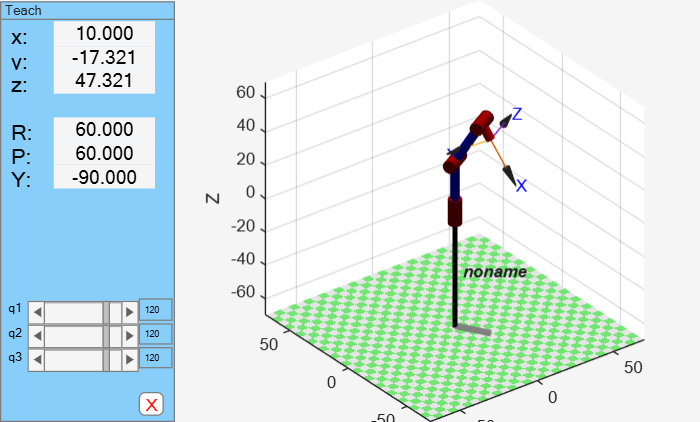


%Position
figure;
KR.plot(q);
KR.teach(q);


%Velocity
disp("Velocities:");

Velocities:


V=J*q';
disp(V);

   45.3450
    5.2360
  -52.3599
    3.6276
    2.0944
    2.0944




Linear_V=V(1:3);
Angular_V=V(4:6);

disp("Linear Velocities:");

Linear Velocities:


disp(Linear_V);

   45.3450
    5.2360
  -52.3599



disp("Angular velocities:");

Angular velocities:


disp(Angular_V);

    3.6276
    2.0944
    2.0944




%Singularity
disp("Singularitiy:");

Singularitiy:


w_pos=sqrt(det(J(1:3,:)*J(1:3,:)'));
w_full=sqrt(det(J'*J));
disp(w_pos);

   5.1962e+03



disp(w_full);

   5.2372e+03




r=rank(J);
disp("Rank of Jacobian:")

Rank of Jacobian:


disp(r);

     3




s=svd(J);
disp(min(s));

    9.8501



syms t1 t2 t3 t4 t5 real
th = [t1 t2 t3 t4 t5];             % use as many as N (N = 5 for you)

d_  = sym(di);                     % your d values
a_  = sym(ai);                     % your a values
al_ = sym(round(rad2deg(alpha)))/180*pi;   % exact pi fractions

Ts = sym(eye(4));                  % named Ts so your T array isn't overwritten
z = sym(zeros(3,N)); p = sym(zeros(3,N));
for i = 1:N
    z(:,i) = Ts(1:3,3);
    p(:,i) = Ts(1:3,4);
    A = [cos(th(i)) -sin(th(i))*cos(al_(i))  sin(th(i))*sin(al_(i)) a_(i)*cos(th(i));
         sin(th(i))  cos(th(i))*cos(al_(i)) -cos(th(i))*sin(al_(i)) a_(i)*sin(th(i));
         0           sin(al_(i))             cos(al_(i))            d_(i);
         0           0                       0                      1];
    Ts = simplify(Ts*A);
end
pe = Ts(1:3,4);

Jv = sym(zeros(3,N));
for i = 1:N
    Jv(:,i) = cross(z(:,i), pe - p(:,i));
end

D = simplify(det(Jv(:,1:3)))
F = factor(D)